5.2.1

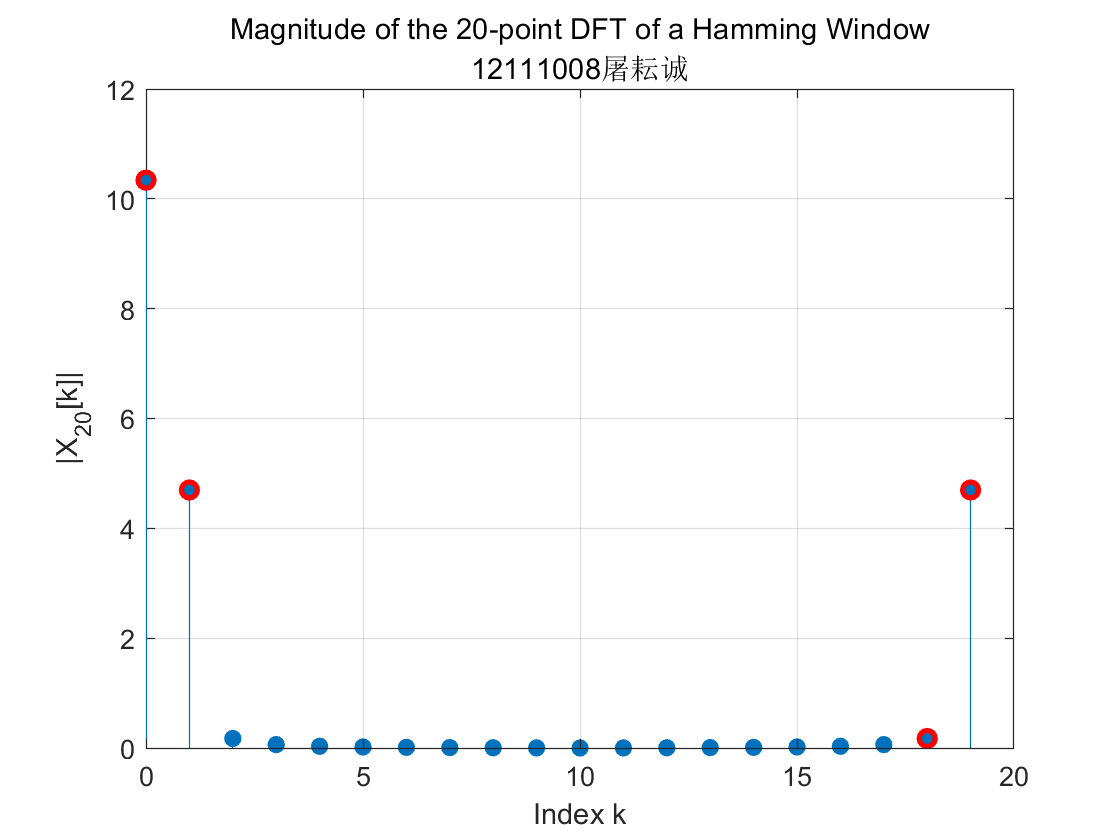

% Create a Hamming window of length N = 20
x = hamming(20);

% Compute the 20-point DFT of x
X = DFTsum(x);

% Plot the magnitude of the DFT
k = 0:19; % Adjusting for MATLAB's 1-based indexing
figure;
stem(k, abs(X), 'filled');
title('Magnitude of the 20-point DFT of a Hamming Window','12111008屠耘诚');
xlabel('Index k');
ylabel('|X_{20}[k]|');
grid on;
% Highlighting low-frequency components
% These are typically at the start and end of the spectrum
hold on;
low_freq_indices = [1, 2, 19, 20];
scatter(low_freq_indices - 1, abs(X(low_freq_indices)), 'red', 'LineWidth', 2);
hold off;

Plot of DTFTsamples of hamming window with *𝑁 *= 20.

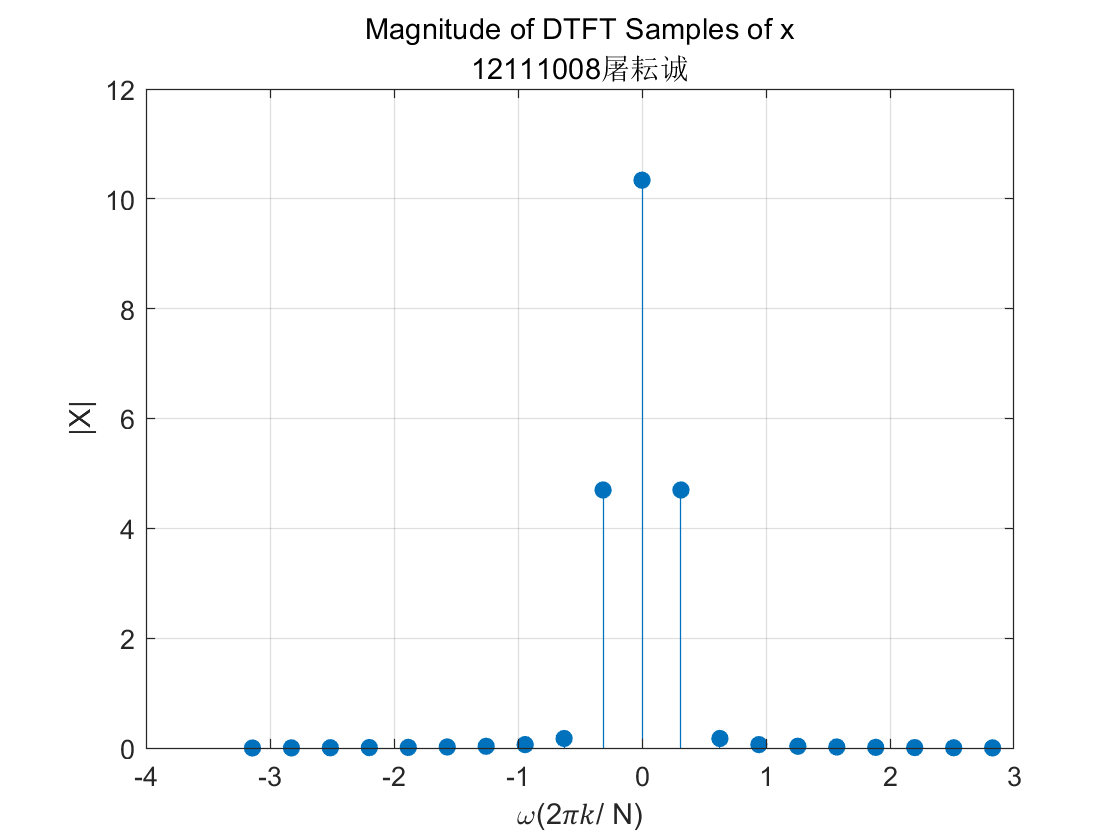

% Use the DTFTsamples function to compute DTFT samples
% of the Hamming window of length N = 20
x = hamming(20);
[X, w] = DTFTsamples(x);

% Plot the magnitude of the DTFT samples versus frequency
figure;
stem(w, abs(X), 'filled');
title('Magnitude of DTFT Samples of x','12111008屠耘诚');
xlabel('\omega(2𝜋𝑘/ N)');
ylabel('|X|');
grid on;

**5.2.2 Zero Padding**

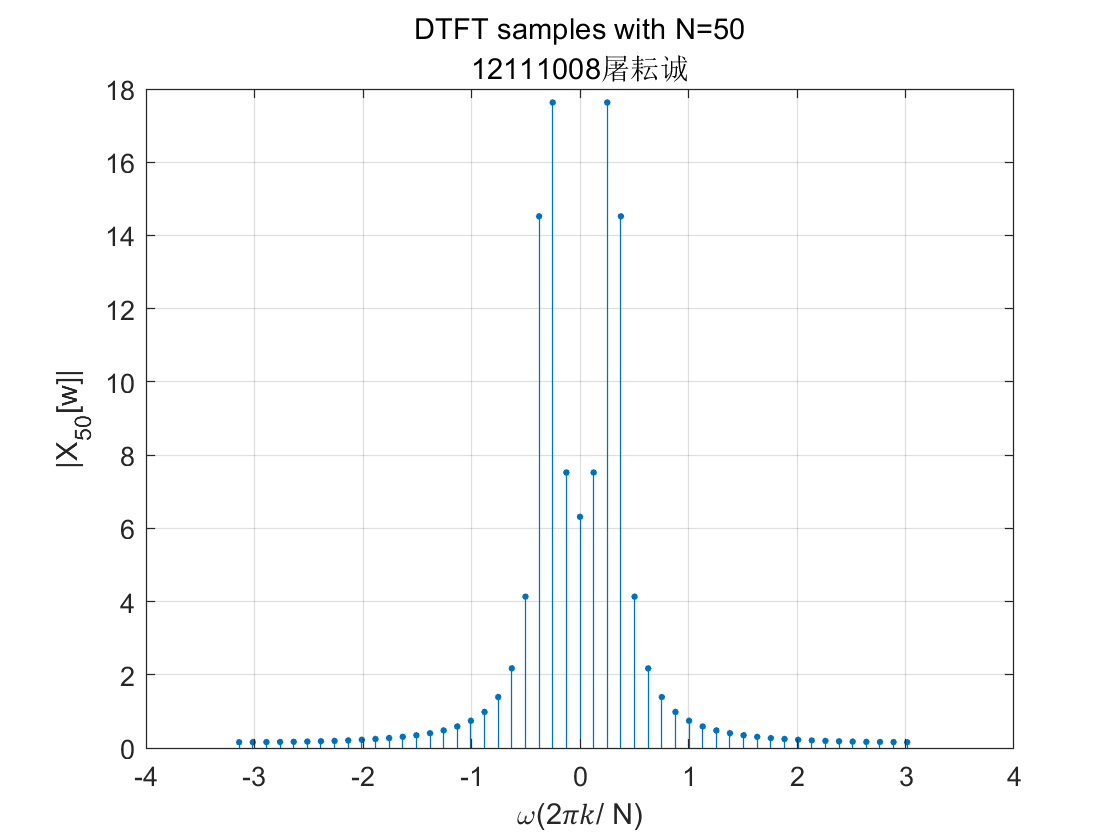

N=50;
n=0:49;
x1=sin(0.1*pi*n);
[X1,w] = DTFTsamples(x1);
figure
stem(w,abs(X1), 'filled','MarkerSize', 2),title('DTFT samples with N=50','12111008屠耘诚')
xlim([-4,4])
xlabel('\omega(2𝜋𝑘/ N)'),ylabel('|X_{50}[w]|')
grid on;

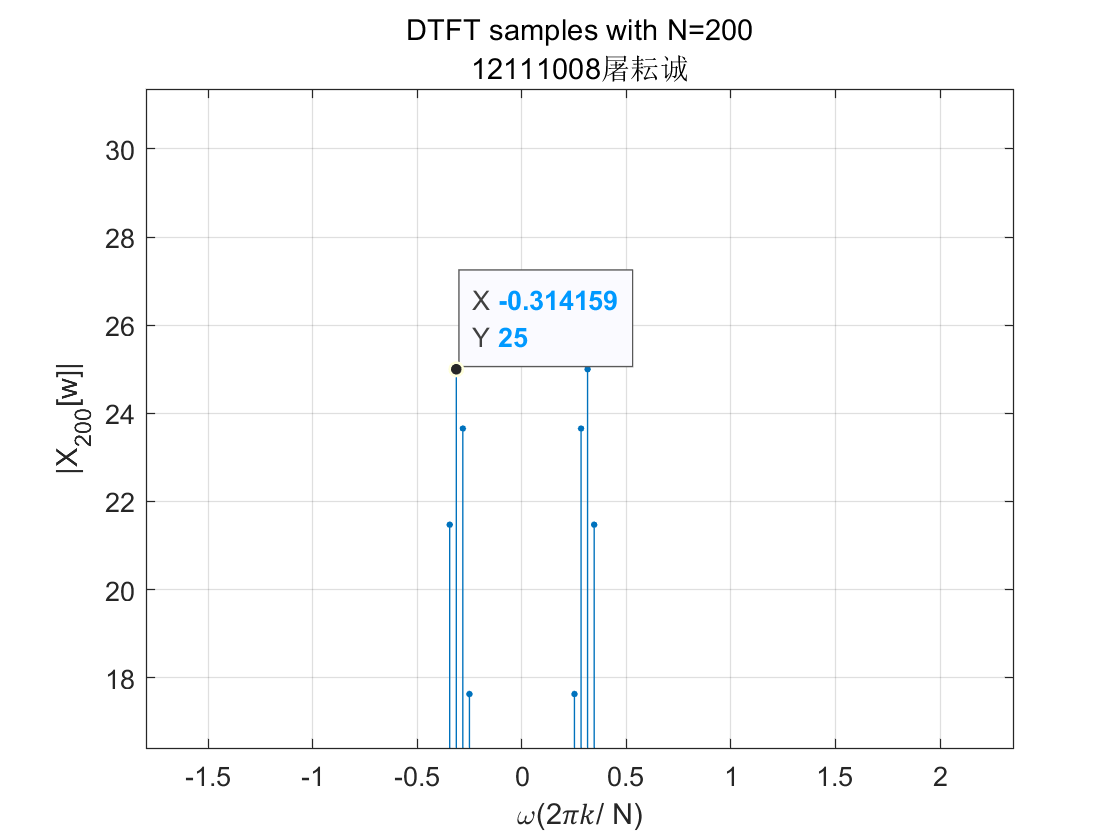


N=200;
x2=[sin(0.1*pi*n) zeros(1,N-50)];
[X2,w] = DTFTsamples(x2);
figure
stem(w, abs(X2), 'filled','MarkerSize', 2),

title('DTFT samples with N=200','12111008屠耘诚')
xlim([-4,4])
xlabel('\omega(2𝜋𝑘/ N)'),ylabel('|X_{200}[w]|')
grid on;

**5.3.1 Implementation of Divide-and-Conquer DFT**

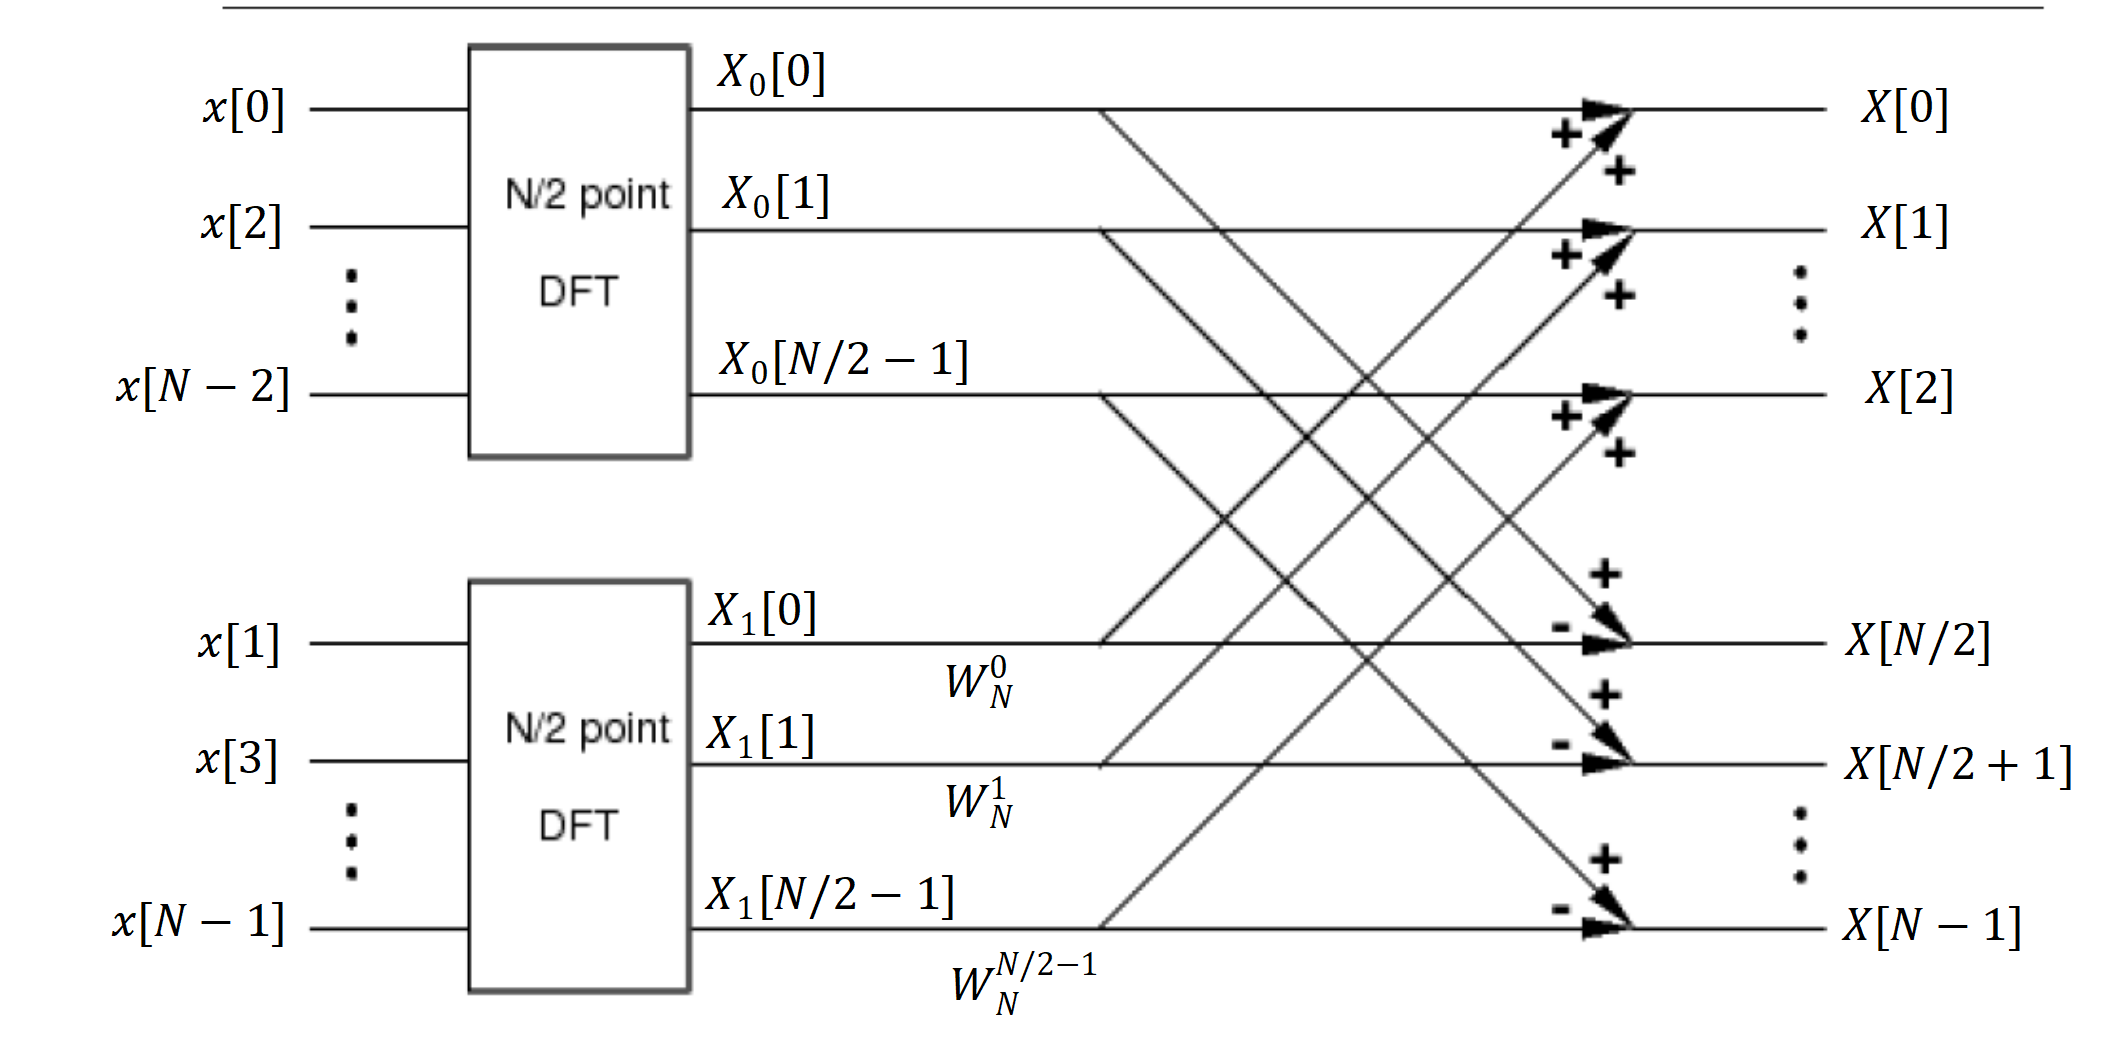

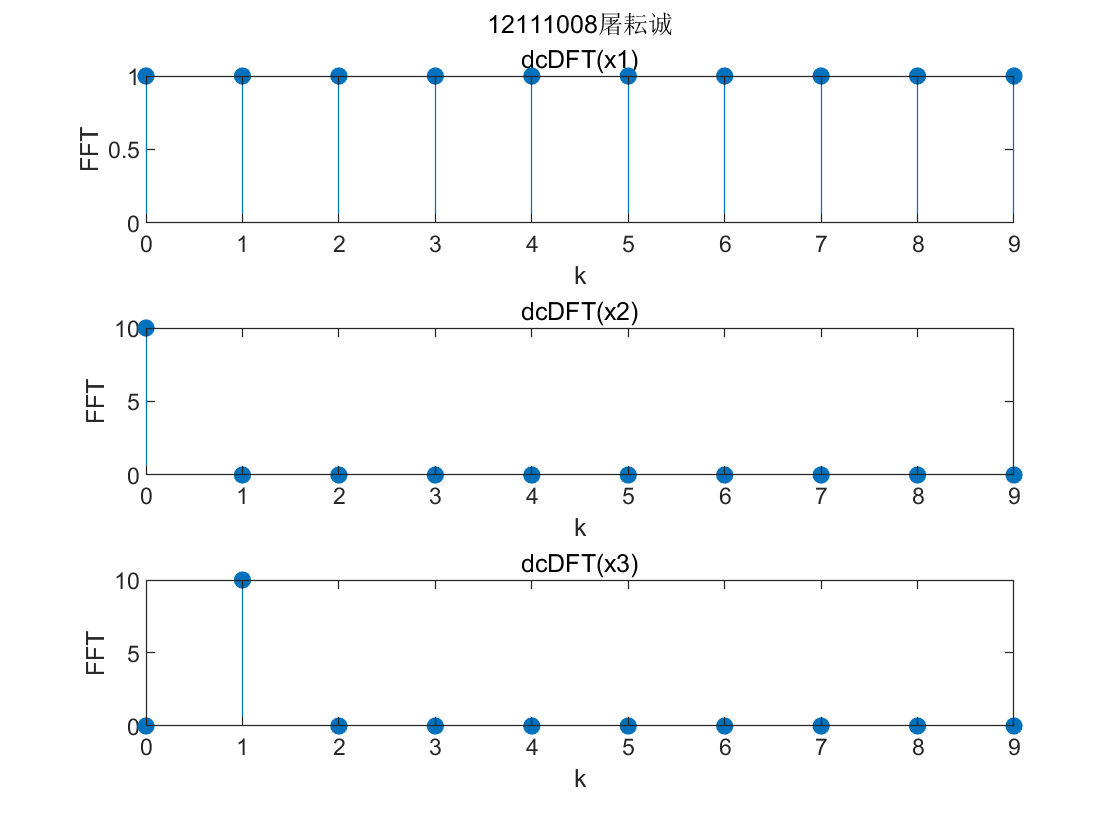


clear
N=10;
n=0:9;
x1=(n==0);
x2=ones(1,N);
x3=exp(1j*2*pi*n/N);
X1_dcDFT=dcDFT(x1);
X2_dcDFT=dcDFT(x2);
X3_dcDFT=dcDFT(x3);
X1_DFT=DFTsum(x1);
X2_DFT=DFTsum(x2);
X3_DFT=DFTsum(x3);

figure
subplot(311)
stem(n,abs(X1_dcDFT),"filled"),title('12111008屠耘诚','dcDFT(x1)')
xlabel('k'),ylabel('FFT')
subplot(312),
stem(n,abs(X2_dcDFT),"filled"),title('dcDFT(x2)')
xlabel('k'),ylabel('FFT')
subplot(313),
stem(n,abs(X3_dcDFT),"filled"),title('dcDFT(x3)')
xlabel('k'),ylabel('FFT')

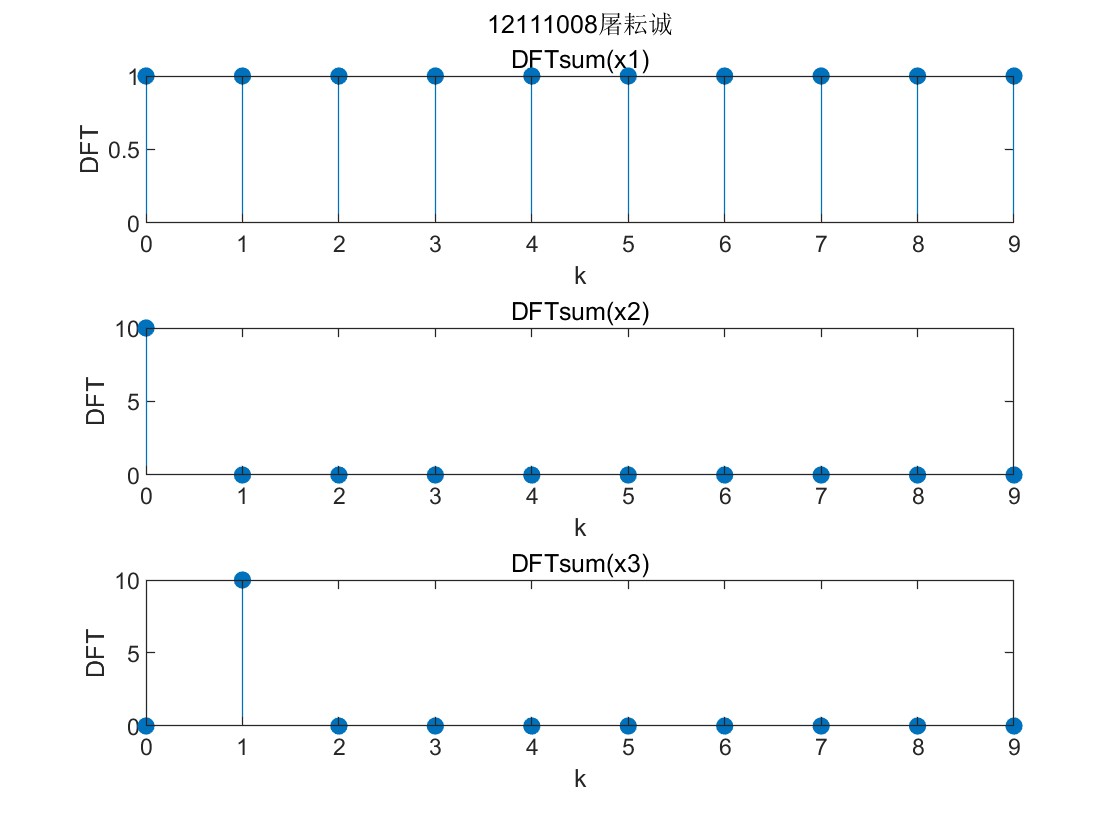

%2*(N/2)^2+N


figure
subplot(311)
stem(n,abs(X1_DFT),"filled"),title('12111008屠耘诚','DFTsum(x1)')
xlabel('k'),ylabel('DFT')
subplot(312)
stem(n,abs(X2_DFT),"filled"),title('DFTsum(x2)')
xlabel('k'),ylabel('DFT')
subplot(313),
stem(n,abs(X3_DFT),"filled"),title('DFTsum(x3)')
xlabel('k'),ylabel('DFT')

5.3.2

clear
N=8;
n=0:N-1;
x1=(n==0);
x2=ones(1,N);
x3=exp(1j*2*pi*n/8);

X1_FFT8=FFT8(x1);
X2_FFT8=FFT8(x2)

X2_FFT8 =      8     0     0     0     0     0     0     0


X3_FFT8=FFT8(x3);
X1_DFT=DFTsum(x1);
X2_DFT=DFTsum(x2)

X2_DFT =    8.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i


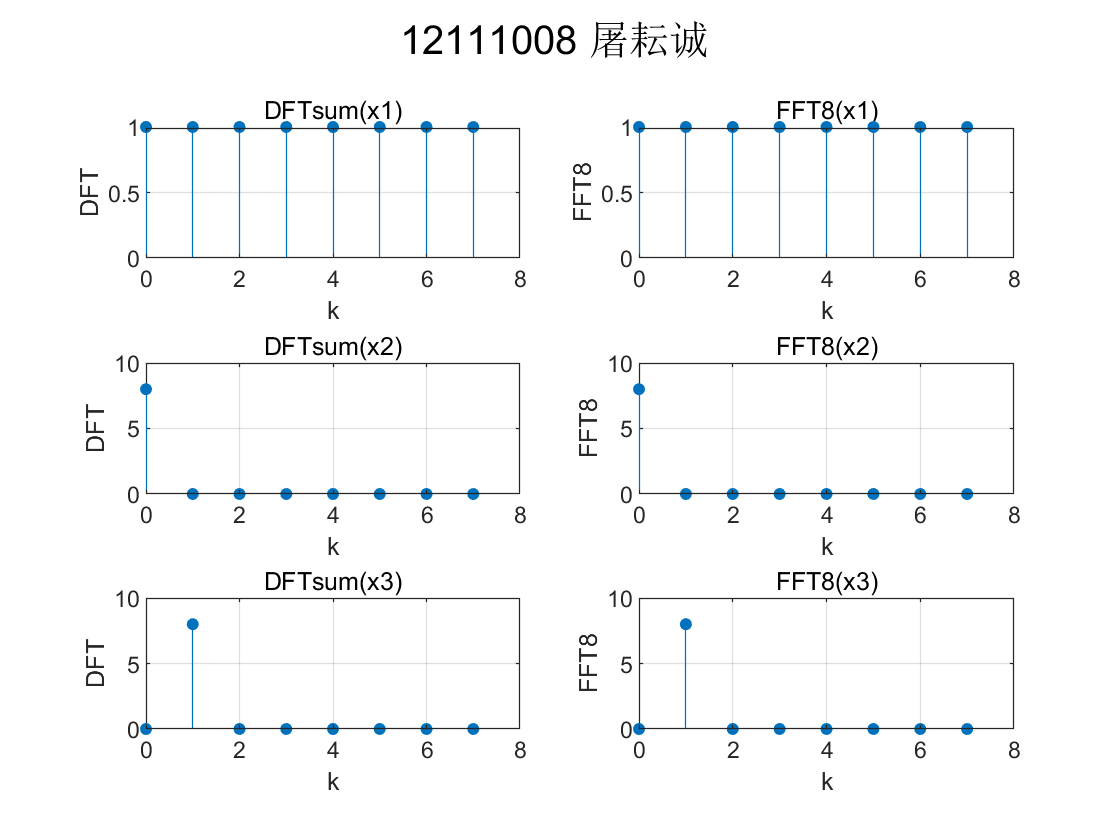

X3_DFT=DFTsum(x3);

figure
sgtitle('12111008 屠耘诚 ')
subplot(3,2,1)
stem(n,abs(X1_DFT),'filled','MarkerSize', 4),title('DFTsum(x1)')
xlabel('k'),ylabel('DFT'),grid on
subplot(3,2,3)
stem(n,abs(X2_DFT),'filled','MarkerSize', 4),title('DFTsum(x2)')
xlabel('k'),ylabel('DFT'),grid on
subplot(3,2,5),
stem(n,abs(X3_DFT),'filled','MarkerSize', 4),title('DFTsum(x3)')
xlabel('k'),ylabel('DFT'),grid on
subplot(3,2,2)
stem(n,abs(X1_FFT8),'filled','MarkerSize', 4),title('FFT8(x1)')
xlabel('k'),ylabel('FFT8'),grid on
subplot(3,2,4),
stem(n,abs(X2_FFT8),'filled','MarkerSize', 4),title('FFT8(x2)')
xlabel('k'),ylabel('FFT8'),grid on
subplot(3,2,6),
stem(n,abs(X3_FFT8),'filled','MarkerSize', 4),title('FFT8(x3)')
xlabel('k'),ylabel('FFT8'),grid on

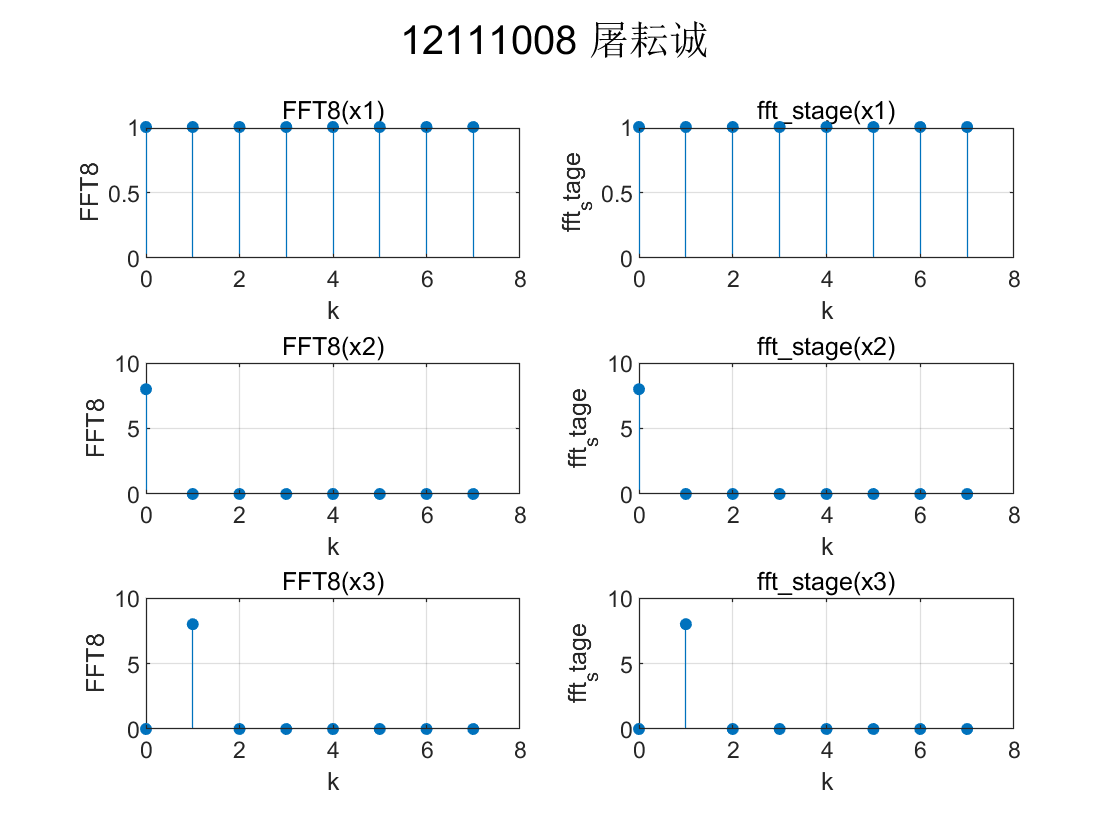


clear
N=8;
n=0:N-1;
x1=(n==0);
x2=ones(1,N);
x3=exp(1j*2*pi*n/8);

X1=fft_stage(x1);
X2=fft_stage(x2);
X3=fft_stage(x3);
X1_0=FFT8(x1);
X2_0=FFT8(x2);
X3_0=FFT8(x3);

figure
sgtitle('12111008 屠耘诚 ')
subplot(321)
stem(n,abs(X1_0),'filled','MarkerSize', 4),title('FFT8(x1)')
xlabel('k'),ylabel('FFT8'),grid on
subplot(323)
stem(n,abs(X2_0),'filled','MarkerSize', 4),title('FFT8(x2)')
xlabel('k'),ylabel('FFT8'),grid on
subplot(325),
stem(n,abs(X3_0),'filled','MarkerSize', 4),title('FFT8(x3)')
xlabel('k'),ylabel('FFT8'),grid on
subplot(322)
stem(n,abs(X1),'filled','MarkerSize', 4),title('fft\_stage(x1)')
xlabel('k'),ylabel('fft_stage'),grid on
subplot(324),
stem(n,abs(X2),'filled','MarkerSize', 4),title('fft\_stage(x2)')
xlabel('k'),ylabel('fft_stage'),grid on
subplot(326),
stem(n,abs(X3),'filled','MarkerSize', 4),title('fft\_stage(x3)')
xlabel('k'),ylabel('fft_stage'),grid on